IOrig = imread("muenzenVerdeckung.jpg");
imshow(IOrig);

d = drawline;
pos = d.Position;
diffPos = diff(pos);
diameter = round(hypot(diffPos(1), diffPos(2)));

[centers, radii] = imfindcircles(IOrig, [round(diameter * 0.25), diameter], ...
    "EdgeThreshold", 0.25, "Sensitivity", 0.97);


centers

centers = 1.0e+03 *

    0.5033    0.4014
    0.7244    0.3421
    0.9526    0.1051
    0.9681    0.6443
    0.4633    0.3043
    1.1044    0.2533
    0.3734    0.0840
    1.0754    0.4669
    0.7259    0.1017
    0.5253    0.5475


radii

radii =    89.4104
  121.6498
  103.7182
   79.2911
  114.0422
   79.9383
  110.2565
  118.1606
  106.0441
  107.4709


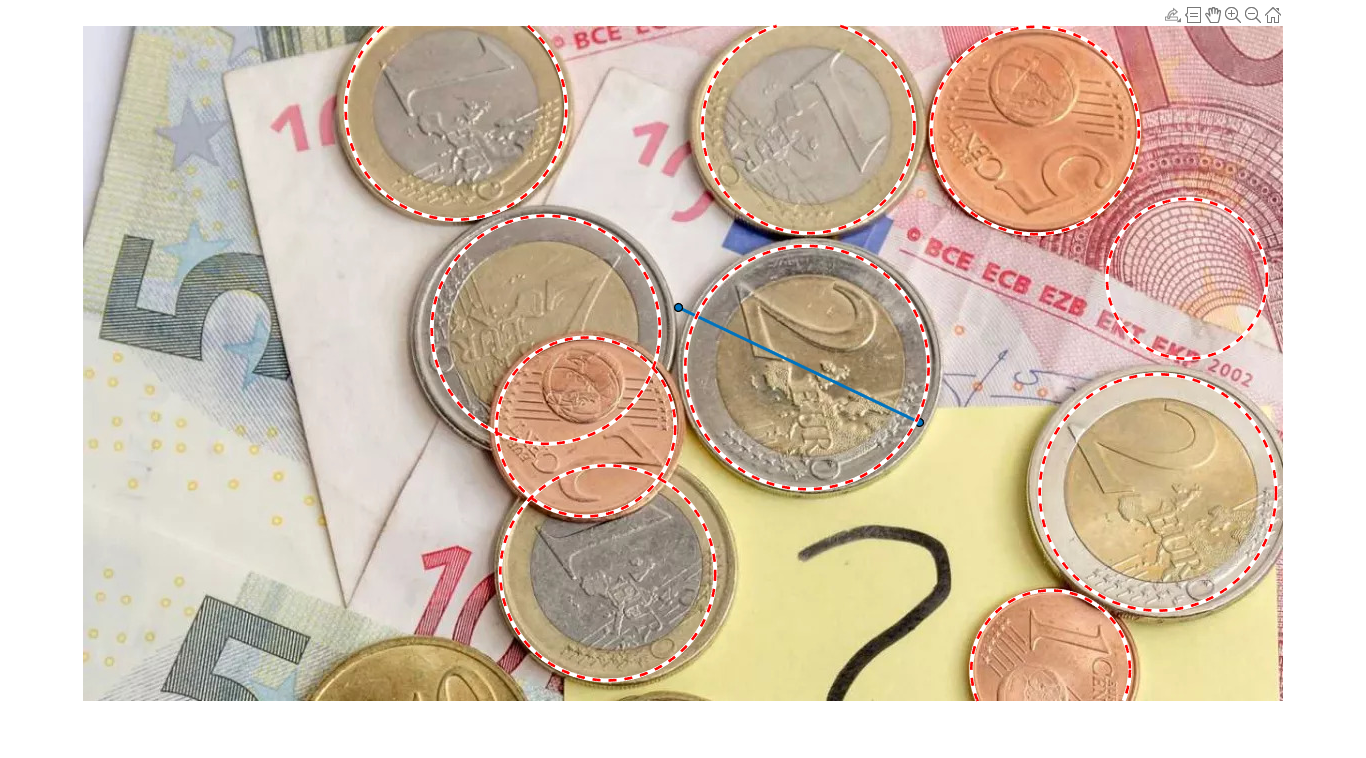

viscircles(centers, radii);


IPadded = padarray(IOrig, [500, 500], 0, 'both');

coinCount = size(centers, 1);

coins = {1, coinCount};

for i = 1:coinCount
    x = round(centers(i, 1)) - 20;
    y = round(centers(i, 2)) - 20;
    r = round(radii(i));
    coins{i} = imcrop(IOrig, [x - r, y - r, 2 * r + 40, 2* r + 40]);

    str = sprintf("readCoins/img_%02d.jpg",i);
    imwrite(coins{i}, str);

end